## `Building and testing HRP`

format long

## De Prado 3 asset dummy case:

Initial correlation matrix. 

correlation_m = [1, 0.7, 0.2; 0.7, 1, -0.2; 0.2, -0.2, 1]

correlation_m =    1.000000000000000   0.700000000000000   0.200000000000000
   0.700000000000000   1.000000000000000  -0.200000000000000
   0.200000000000000  -0.200000000000000   1.000000000000000


**Call 1.1** to check results agains R output:

test_dist1 = correlDist(correlation_m)

test_dist1 =                    0   0.387298334620742   0.632455532033676
   0.387298334620742                   0   0.774596669241483
   0.632455532033676   0.774596669241483                   0


TESTED: works 

**Call 1.2 **(NOT NEEDED)

test_dist2 = Euc_dist(test_dist1)

test_dist2 =                    0   0.565865799361234   0.974679434480896
   0.565865799361234                   0   1.122542672437607
   0.974679434480896   1.122542672437607                   0


TESTED: works 

**Call 1.3 Cluster Linkage function**

Used dist1 = correlation differences. 

den =   2×1 Line array:

  Line
  Line


order =      1
     2
     3


[den,order] = cluster_fn(test_dist1)

TESTED: works to get NB: order of dendrogram 

## De Prado 10 asset case:

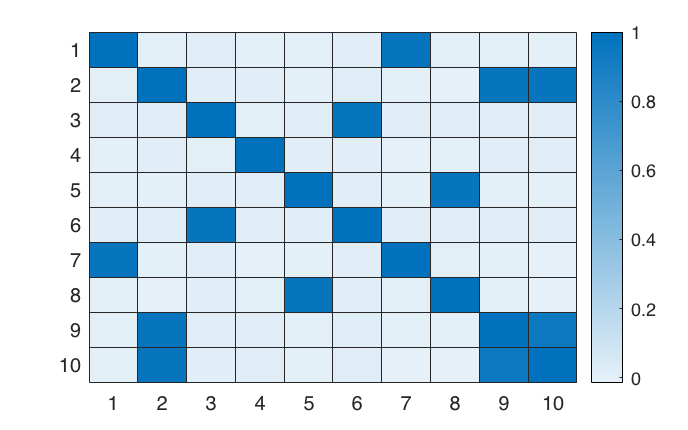

% Import data and convert to matrix
cor_10_asset = readtable('corMat.csv');
cor_10_matrix = table2array(cor_10_asset);

% Fix heat map to flip it
%heatmap(transpose(cor_10_matrix))


% get intial distance matrix of correlations
dist1Lop = correlDist(cor_10_matrix)

dist1Lop =                    0   0.708179295447135   0.703553029273558   0.710877278790088   0.708879483762931   0.704098375939044   0.122347776849439   0.707581580455568   0.707534233094060   0.710287058871271
   0.708179295447135                   0   0.704069579303069   0.704535762754454   0.710430398420563   0.702646650173471   0.710322842093650   0.712297704615142   0.122251910005529   0.119689293589694
   0.703553029273558   0.704069579303069                   0   0.707330864235401   0.706478076446821   0.121480354378805   0.704909540650430   0.706451164271105   0.702695795134708   0.704379793861238
   0.710877278790088   0.704535762754454   0.707330864235401                   0   0.705085278530193   0.706798110849201   0.711165301459513   0.706950172218665   0.702832496402948   0.703842990303946
   0.708879483762931   0.710430398420563   0.706478076446821   0.705085278530193                   0   0.705188436518921   0.710403830226161   0.122478522607027   0.709205599597183   0.

TESTED: works 

## Notes:

- Matlab linkage function used euclidean distance already so no need to calculate Euc first. **Therefore:** removed Euclidean Distance Fn

## **Functions defined:**

### **Stage 1:**** Tree Clustering**

**1.1 distance matrix based on correlation Fn**

Distance matrix based on the returns correlation matrix where distances are: 0 <= d[i,j] <= 1

   function dist = correlDist(corr)
        dist = sqrt((1-corr)/2);
    end

**1.2 Euclidean Distance Fn**

(Defined but not used)

    function Euclidean_d = Euc_dist(distance)
        D = pdist(distance);
        Euclidean_d = squareform(D);
        
    end 

### **Stage 2:**** Quasi-Diagonalization**

Get horizontal order of cluster formation in dendrogram 

**2.1 get Quasi-Diagonalized Asset Ordering**

    function [den,order] = cluster_fn(dist)
       clus = linkage(dist,"single", "euclidean");
       [den,order] = dendrogram(clus);
    end

### **Stage 3:**** Recursive Bisection **

Get horizontal order of cluster formation in dendrogram 

**2.1 get Quasi-Diagonalized Asset Ordering**